# 16  QUADRATIC PROGRAMMING

An optimization problem with a quadratic objective function and linear constraints.

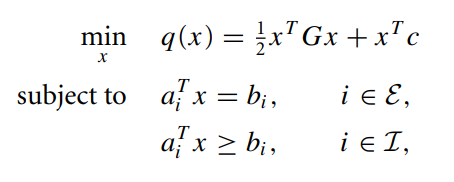

where

- $G$ is a symmetric $n\times n$ matrix,

- $\mathcal{E}, \mathcal{I}$ are finite sets of indices,

- 
$$c, x, a_i\in \mathbb{R}^n$$


Remarks

- If $G$ is positive semidefinite, it is called **convex** QP.

- If $G$ is positive definite, it is called **strictly convex** QP.

- If $G$ is positive indefinite, it is called **nonconvex** QP.

## 16.1 EQUALITY-CONSTRAINED QUADRATIC PROGRAMS

For simplicity,

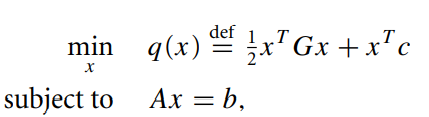 

where 

- $A$ is the $m \times  n$ Jacobian of constraints (with $m \le  n$) whose rows are $a^T_ i , i \in  \mathcal{E$ and 

- $b$ is the vector in $\mathbb{R}^m$ whose components are $b_i , i \in  \mathcal{E}$.

First order condition for optimality 

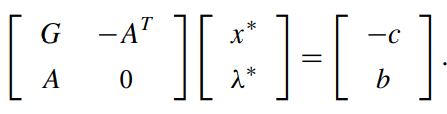 (*)

(see Theorem 12.1)

We can rewrite this system to get

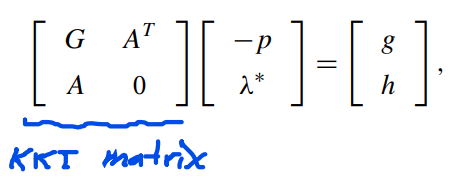

where

Let $Z$ denote the $n \times  (n - m)$ matrix whose columns are a basis for the null space of $A$. That is, $Z$ has full rank and satisfies $AZ= 0$.

**Lemma:**

Let $A$ have full row rank, and assume that the reduced-Hessian matrix $Z^T G Z$ is positive definite. Then the KKT matrix

 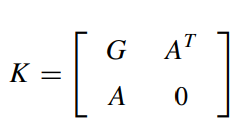

is nonsingular, and hence there is a **unique** vector pair $(x^\ast  , \lambda ^\ast )$ satisfying (*).

Proof: In class

### Solving the KKT system

** Direct methods**

- Symmetric indefinite factorization $P^TKP=LBL^T$. (forward-backward)

- Schur complement method 

- Null-Space method 

** Iterative methods**

- CG applied to the reduced system 

- The projected CG method 

- Newton-Krylov method

### SCHUR-COMPLEMENT METHOD

Assume that $G$ is positive definite, we can get

$(AG^{-1}A^T)\lambda  = (AG^{-1}g - h).$ (How?)

- solve for $\lambda^*$ then

- solve for p in $-Gp +A^T \lambda ^\ast  = g$

### NULL-SPACE METHOD

- The null-space method does not require nonsingularity of G and therefore has wider applicability than the Schur-complement method.

- Assume that $A$ has full row rank and that $Z^TGZ$ is positive definite.

Suppose we write $p$ as 

                $p=Y p_Y + Z p_Z$, 

where 

- $Z$ is the $n \times  (n - m)$ null-space matrix, 

- $Y$ is any $n \times  m$ matrix such that $[Y | Z]$ is nonsingular, 

- $p_Y$ is an $m$-vector, and 

- $p_Z$ is an $(n - m)$-vector

From the second equation we have

                    
$$(AY)p_Y =-h$$


and 

                    
$$p_Y=-(AY)^{-1}h$$


A = [1 0 1;0 1 1];
x=zeros(3,1);
G = [6 2 1;2 5 2;1 2 4];
h = -[3;0];
g = [-8;-3;-3];
Z = [1;1;-1];
Y = [1 0;0 1;0 0];
pY=-h;
pz = (1/(Z'*G*Z))*(-Z'*G*Y*pY-Z'*g);
p = Y*pY+Z*pz;
xs = x + p;
ls = Y'*(g + G*p);
